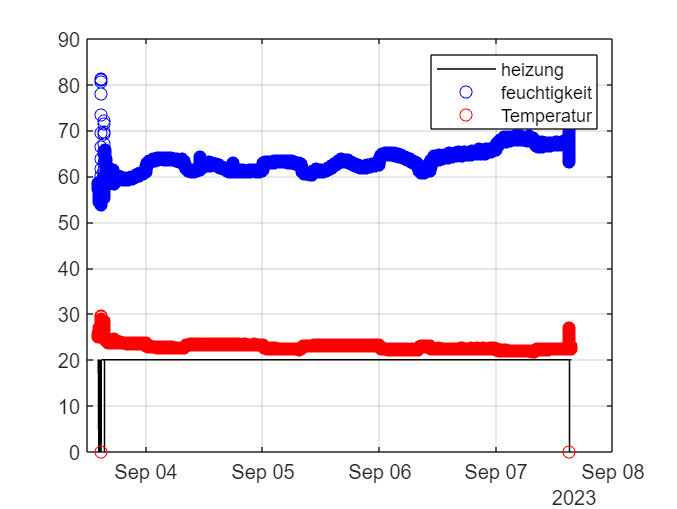

close all
clear
clc

a = readtable("C:\Users\domin\OneDrive\Raspberry Pico\data_log_4.txt",'Delimiter',';');
a.datetime = datetime(a.datetime,'InputFormat','(yyyy,MM,dd,HH,mm,ss)');
a = table2timetable(a);


%%
%S= timerange(a.datetime(40000),a.datetime(end));
%stackedplot(a(S,:))

%%

a.Properties.VariableNames;

plot(a.datetime ,a.relay_AC_3*20,'k')
hold on
scatter(a.datetime ,a.Humidity,'blue')
scatter(a.datetime,a.Temperatur,'red')
legend("heizung","feuchtigkeit","Temperatur")
grid on
%%
hold off

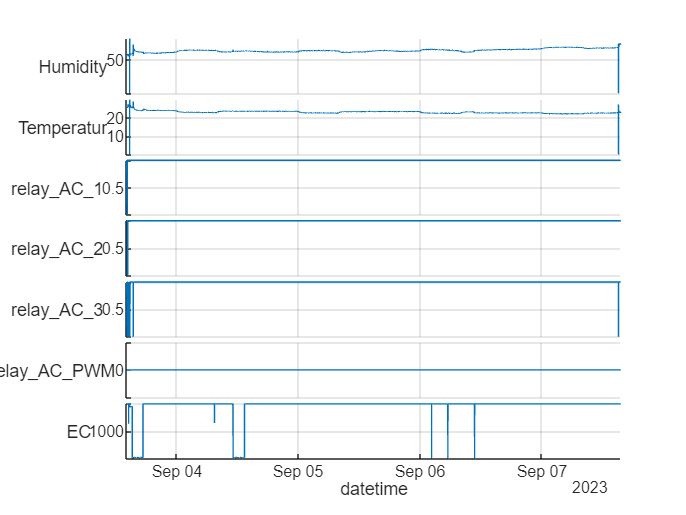


S= timerange(datetime("29-08-2023 21:00:00","InputFormat","dd-MM-yyyy HH:mm:ss"),a.datetime(end));
stackedplot(a(S,:),{'Humidity','Temperatur','relay_AC_1','relay_AC_2','relay_AC_3','relay_AC_PWM','EC'})
grid on

%%
set = a(S,:);


















